% mikexcohen.com

## convolution in a small example

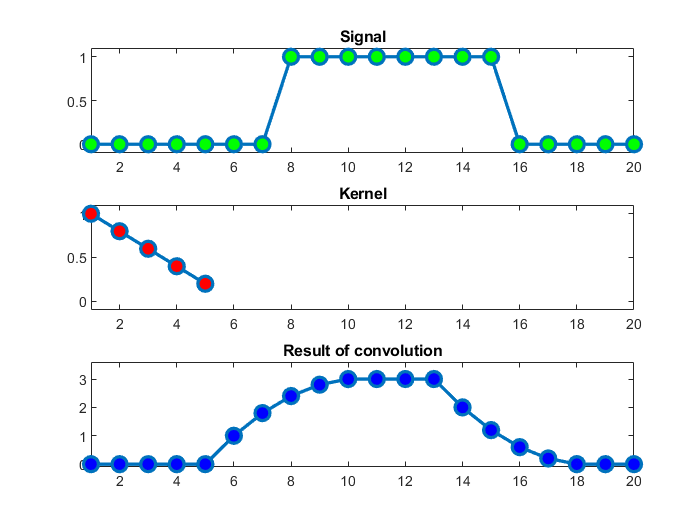

% signal
signal = zeros(1,20);
signal(8:15)=1;

kernel = [1 .8 .6 .4 .2];

% matlab's convolution function
matlab_conv_result = conv(signal,kernel,'same'); 
% return the same length as the signal (cutting off the beginning and the end)

figure(1), clf
% plot the signal (impulse or boxcar)
subplot(311)
plot(signal,'o-','linew',2,'markerface','g','markersize',9)
set(gca,'ylim',[-.1 1.1],'xlim',[1 20])
title('Signal')

% plot the kernel
subplot(312)
plot(kernel,'o-','linew',2,'markerface','r','markersize',9)
set(gca,'xlim',[1 20],'ylim',[-.1 1.1])
title('Kernel')

% plot the result of convolution
subplot(313)
plot(matlab_conv_result,'o-','linew',2,'markerface','b','markersize',9)
set(gca,'xlim',[1 20],'ylim',[-.1 3.6])
title('Result of convolution')

## "manual" time-domain convolution

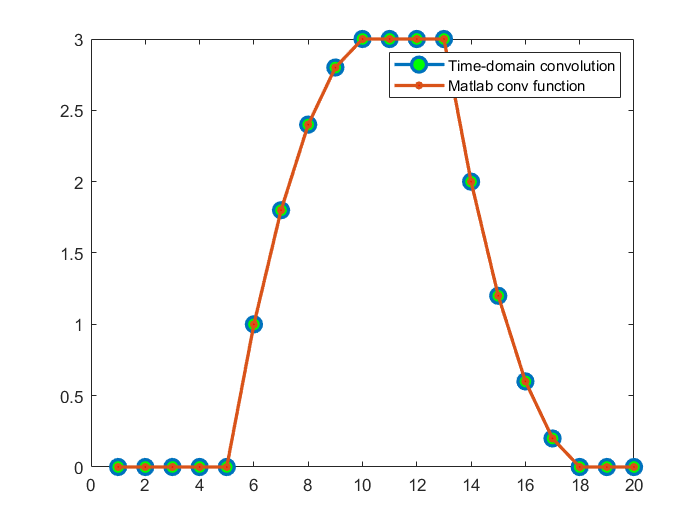

half_kernel = floor(length(kernel)/2);

% EEG data that we'll use for convolution (must be zero-padded).
dat4conv = [ zeros(1,half_kernel) signal zeros(1,half_kernel) ];

% initialize convolution output
conv_res = zeros(1,length(signal)+length(kernel)-1);

% run convolution
for ti=1:length(dat4conv)-length(kernel)
    tempdata = dat4conv(ti:ti+length(kernel)-1);
    conv_res(ti+half_kernel) = sum( tempdata .* kernel(end:-1:1) );
    % kernel gets flipped around backwards
end

% cut off edges
conv_res = conv_res(half_kernel+1:end-half_kernel);

figure(2), clf

plot(conv_res,'o-','linew',2,'markerface','g','markersize',9)
hold on
plot(matlab_conv_result,'o-','linew',2,'markerface','r','markersize',3)
legend({'Time-domain convolution';'Matlab conv function'})